# Filtr interpolatora i decymatora cyfrowego, mikser audio

Dane Startowe

f1 = 1001.2; fs1 = 8e3;
f2 =  303.1; fs2 = 32e3;
f3 = 2110.4; fs3 = 48e3;

tlimit = 1;
x1 = sin(2*pi*f1*[0:1/fs1:tlimit-1/fs1]);
x2 = sin(2*pi*f2*[0:1/fs2:tlimit-1/fs2]);
x3 = sin(2*pi*f3*[0:1/fs3:tlimit-1/fs3]);

reczny resampling

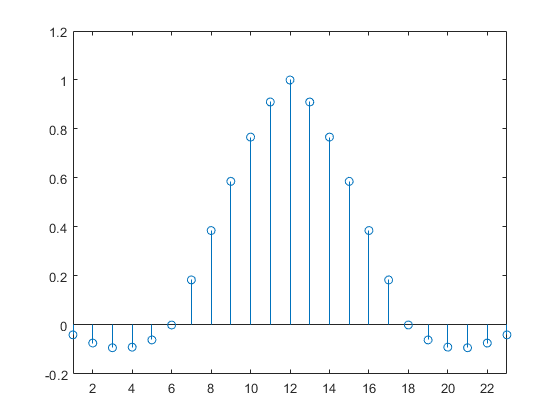

% sig 01
x1up    = upsample(x1,fs3/fs1);
h1      = intfilt(fs3/fs1,2,0.5);

figure
stem(h1)
xlim([1 23])


x1int   = filter(h1,1,x1up);

delay = mean(grpdelay(h1))

delay = 11

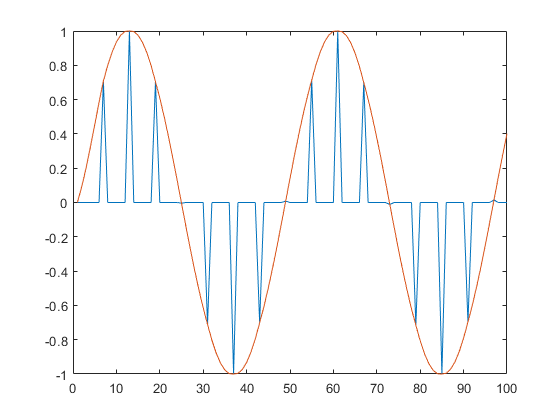

x1int(1:delay) = [];

figure
plot(x1up(1:100))
hold on
plot(x1int(1:100))


% sig 02
x2up    = upsample(x2,3);
h2      = intfilt(3,2,0.3);
x2int   = filter(h2,1,x2up);
delay   = mean(grpdelay(h2))

delay = 5

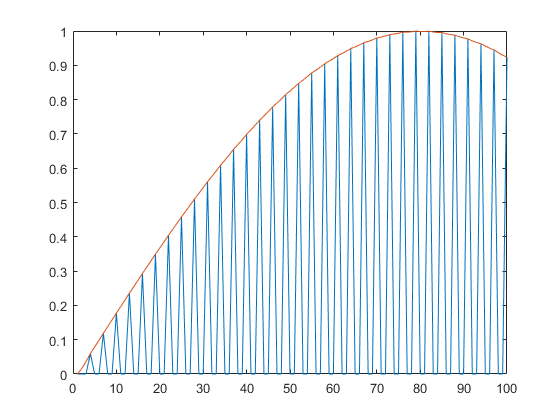

x2int(1:delay) = [];

x2dec   = decimate(x2int, 2);


figure
plot(x2up(1:100))
hold on
plot(x2int(1:100))

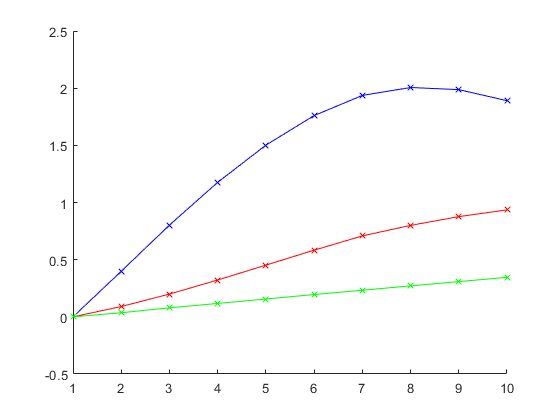



% suma

x4 = x1int + x2dec(1:end-9) + x3(1:end-11);

figure
hold on
plot(x4(1:10),'bx-')
plot(x1int(1:10),'rx-')
plot(x2dec(1:10),'gx-')